# ODE Lab: Creating your own ODE solver in MATLAB

In this lab, you will write your own ODE solver for the Improved Euler method (also known as the Heun method), and compare its results to those of `ode45`.

You will also learn how to write a function in a separate m-file and execute it.

Opening the m-file lab3.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are six (6) exercises in this lab that are to be handed in on the due date. Write your solutions in the template, including appropriate descriptions in each step. Save the .m files and submit them online on Quercus.

## Student Information

Student Name: Patricia Nadia Krisanti

Student Number: 1009669404

## Creating new functions using m-files.

Create a new function in a separate m-file:

Specifics: Create a text file with the file name f.m with the following lines of code (text):

Now MATLAB can call the new function f (which simply accepts 3 numbers and adds them together). To see how this works, type the following in the matlab command window: sum = f(1,2,3)

## Exercise 1

Objective: Write your own ODE solver (using the Heun/Improved Euler Method).

Details: This m-file should be a function which accepts as variables (t0,tN,y0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0 is the initial condition of the ODE, and h is the stepsize. You may also want to pass the function into the ODE the way `ode45` does (check lab 2).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

x=ode45(@(x,y) y, [0,10] ,1)

%the ODE solver that I have written is as follows
%{
function y=f(f, t0, tN, y0, h) %f,start, endpoint, initial condition, stepsize

x=t0:h:tN;
disp(x);
y=zeros(size(x));
y(1)=y0;
num=size(x);
for i=1:(num(2)-1)
    sol=f((x(i)+h)  ,  (y(i)+  h.*f(x(i),y(i)) )  );
    y(i+1)=((sol+f(x(i),y(i)))./2).*h   +  y(i);
end
y(1)=y0;
s=ode45(f, [t0,tN] ,y0);
plot(x,y,s.x,s.y,'x');
legend("mine", "ode45")
end

%}


## Exercise 2

Objective: Compare Heun with `ode45`.

Specifics: For the following initial-value problems (from lab 2, exercises 1, 4-6), approximate the solutions with your function from exercise 1 (Improved Euler Method). Plot the graphs of your Improved Euler Approximation with the `ode45` approximation.

(a) `y' = y tan t + sin t, y(0) = -1/2` from `t = 0` to `t = pi`

(b) `y' = 1 / y^2 , y(1) = 1` from `t=1` to `t=10`

(c) `y' = 1 - t y / 2, y(0) = -1` from `t=0` to `t=10`

(d) `y' = y^3 - t^2, y(0) = 1` from `t=0` to `t=1`

Comment on any major differences, or the lack thereof. You do not need to reproduce all the code here. Simply make note of any differences for each of the four IVPs.

%{
For all the graphs, both improved Euler Approximation with the ode45 and
function that I made from exercise works fine. It shows the exact
same graph using both approximations
The only difference there is is on the last function, function d,
where the ode45 could not continue
producing the approximations after t=5.066046e-01 and produces the following error
message
Warning: Failure at t=5.066046e-01.  Unable to meet integration tolerances without reducing the step size below the smallest value allowed (1.776357e-15) at time t. 
> In ode45 (line 350)
In f (line 13) 

This is because in the function that I made, I manually use the step size
to increment the x, resulting in an infinite value of y when the function
is trying to evaluate for y. This does not result in an error because I
have no integration tolerances like the ode45.

%}

## Exercise 3

Objective: Use Euler's method and verify an estimate for the global error.

Details: 

(a) Use Euler's method (you can use euler.m from iode) to solve the IVP

`y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0`

from `t=0` to `t=0.5`.

(b) Calculate the solution of the IVP and evaluate it at `t=0.5`.

(c) Read the attached derivation of an estimate of the global error for Euler's method. Type out the resulting bound for En here in a comment. Define each variable.

(d) Compute the error estimate for `t=0.5` and compare with the actual error.

(e) Change the time step and compare the new error estimate with the actual error. Comment on how it confirms the order of Euler's method.

% a) Use Euler's method (you can use euler.m from iode) to solve the IVP
%setting up the inline functions to calculate the solution
f=@(t,y) 2*t*sqrt( 1 - y.^2 )

f = function_handle with value:
    @(t,y)2*t*sqrt(1-y.^2)


xc=euler(f, 0, 0:0.01:0.5) %using euler.m 

xc =          0         0    0.0002    0.0006    0.0012    0.0020    0.0030    0.0042    0.0056    0.0072    0.0090    0.0110    0.0132    0.0156    0.0182    0.0210    0.0240    0.0272    0.0306    0.0342    0.0380    0.0420    0.0462    0.0506    0.0552    0.0600    0.0650    0.0701    0.0755    0.0811    0.0869    0.0929    0.0990    0.1054    0.1120    0.1187    0.1257    0.1328    0.1402    0.1477    0.1554    0.1633    0.1714    0.1797    0.1881    0.1968    0.2056    0.2146    0.2238    0.2331


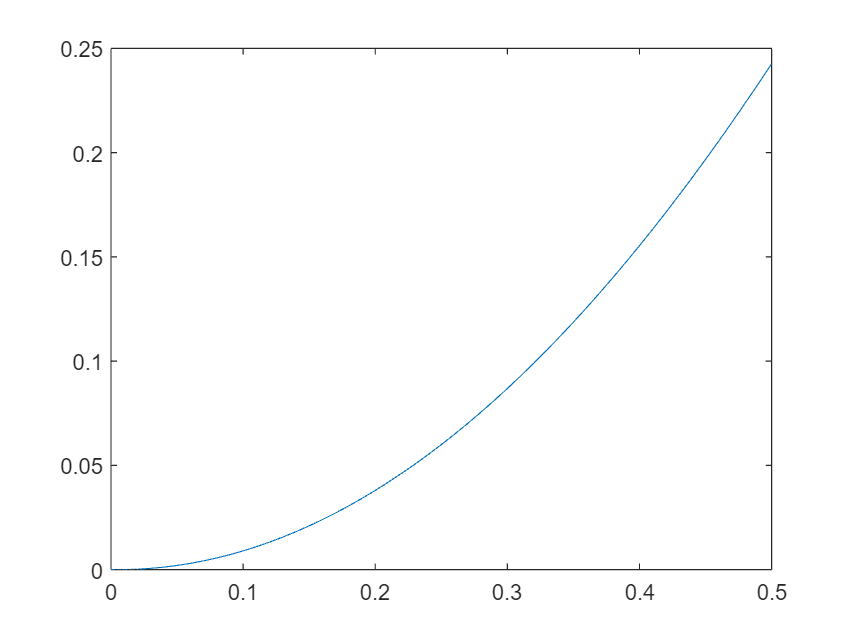

plot(0:0.01:0.5, xc)


% (b) Calculate the solution of the IVP and evaluate it at t=0.5.
%the solution for the IVP is y=sin(t^2)
%t=0.5 means it will be on column 0.5/0.01 +1 = 50 +1 or the last column of xc
fprintf("solution to IVP at t=0.5 is %g", xc(51))

solution to IVP at t=0.5 is 0.242672


% (c) Read the attached derivation of an estimate of the global error for Euler's method. 
% Type out the resulting bound for En here in a comment. Define each variable.
% En=|yn-y(tn)|  approximate solution - true solution
% En<=1/(1+Mh) * (exp(Mhn)-1)
% where
% M = upper bound
% n = step count (number of step)
% h = step size
% En is the error estimation for euler's method

%d
En=abs(sin(0.5^2)-xc(51))

En = 0.0047


f=@(t,y) 2*t*sqrt( 1 - y.^2 )

f = function_handle with value:
    @(t,y)2*t*sqrt(1-y.^2)


xc=euler(f, 0, 0:0.001:0.5) %using euler.m 

xc =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024



%e
En=abs(sin(0.5^2)-xc(501))

En = 4.7230e-04

%the smaller the timestep, the smaller the error. Which means the euler's method
% becomes more and more precise with a smaller timestep. This confirms Euler's
%method of solving ODE.

## Adaptive Step Size

As mentioned in lab 2, the step size in `ode45` is adapted to a specific error tolerance.

The idea of adaptive step size is to change the step size `h` to a smaller number whenever the derivative of the solution changes quickly. This is done by evaluating f(t,y) and checking how it changes from one iteration to the next.

## Exercise 4

Objective: Create an Adaptive Euler method, with an adaptive step size `h`.

Details: Create an m-file which accepts the variables `(t0,tN,y0,h)`, as in exercise 1, where `h` is an initial step size. You may also want to pass the function into the ODE the way `ode45` does.

Create an implementation of Euler's method by modifying your solution to exercise 1. Change it to include the following:

(a) On each timestep, make two estimates of the value of the solution at the end of the timestep: `Y` from one Euler step of size `h` and `Z` from two successive Euler steps of size `h/2`. The difference in these two values is an estimate for the error.

(b) Let `tol=1e-8` and `D=Z-Y`. If `abs(D)<tol`, declare the step to be successful and set the new solution value to be `Z+D`. This value has local error `O(h^3)`. If `abs(D)>=tol`, reject this step and repeat it with a new step size, from (c).

(c) Update the step size as `h = 0.9*h*min(max(tol/abs(D),0.3),2)`.

Comment on what the formula for updating the step size is attempting to achieve.

%{
function y=f(f, t0, tN, y0, h) %f,start, endpoint, initial condition, stepsize
%calculate euler solution for Z where h=h/2 and there's twice as much
%timesteps as Y
ori=h;
t=[t0]
y=[y0]
z=[y0]
fin=[y0]
tol=1e-8 %this takes foreverrrr (at least on my laptop) so to test increase the tolerance first..
while t(end)<tN
    t(end)
    %calculate euler solution for Y with 
    k=f(t(end),y(end)); %y(tn+1) = y(n) + (1/2) * h * (f(tn,yn) + f(tn+h, yn+h*f(tn,yn))
    sol=f((t(end)+h)  ,  (y(end)+  h.*k )  );
    y(end+1)=(sol+k).*(1/2).*h   +  y(end);
   

    k=f(t(end),z(end)); %y(tn+1) = y(n) + (1/2) * h * (f(tn,yn) + f(tn+h, yn+h*f(tn,yn))
    sol=f((t(end)+(h/2))  ,  (z(end)+  (h/2).*k )  );
    z(end+1)=(sol+k).*(1/2).*(h/2)   +  z(end);
    

    k=f(t(end),z(end)); %y(tn+1) = y(n) + (1/2) * h * (f(tn,yn) + f(tn+h, yn+h*f(tn,yn))
    sol=f((t(end)+(h/2))  ,  (z(end)+  (h/2).*k )  );
    z(end)=(sol+k).*(1/2).*(h/2)   +  z(end);
    
    
    D=z(end)-y(end);
    if abs(D)<tol
        fin(end+1)=z(end)+D;
        t(end+1)=t(end)+h;
        h=ori;
    elseif abs(D)>=tol
        
        z(end)=[];
        y(end)=[];
        a=tol/abs(D);
        b=min(max(a,0.3),2);
        h = 0.9*h*b;
        
    end

end
    

    s=ode45(f, [t0,tN] ,y0);
    plot(t,z,t,fin,s.x,s.y,'x');
    legend("y", "ode45")
end

%}

%Comment on what the formula for updating the step size is attempting to achieve.
% the formula is ensuring that h will never be bigger than 0.9*h*2, while maximixing the 
% step size possible by using max(tol/abs(D),0.3). tol/abs(D) is used to
% see how much bigger/smaller the error or difference between Z and Y is
% from the tolerance being set.the formula multiplies this value by 0.9 and
% h to gradually reduce the stepsize when answer is not within the
% tolerance range.

## Exercise 5

Objective: Compare Euler to your Adaptive Euler method.

Details: Consider the IVP from exercise 3.

`y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0`

(a) Use Euler method to approximate the solution from `t=0` to `t=0.75` with `h=0.025`.

(b) Use your Adaptive Euler method to approximate the solution from `t=0` to `t=0.75` with initial `h=0.025`.

(c) Plot both approximations together with the exact solution.

fun=@(t,y) 2*t*sqrt( 1 - y.^2 )

% a
[IVPx,IVPy]=f(fun , 0, 0.75, 0, 0.025);
%b
[AEMx,AEMy]= exercise4(fun , 0, 0.75, 0, 0.025);
%c
%exact solution : y= sin(t^2)
x=linspace(0,0.75,10)
e=sin(x.^2)

plot(x,e,"x", AEMx,AEMy,IVPx,IVPy)
legend("exact solution","Adaptive Euler method", "Improved Euler method")

## Exercise 6

Objective: Problems with Numerical Methods.

Details: Consider the IVP from exercise 3 (and 5).

(a) From the two approximations calculated in exercise 5, which one is closer to the actual solution (done in 3.b)? Explain why.

(b) Plot the exact solution (from exercise 3.b), the Euler's approximation (from exercise 3.a) and the adaptive Euler's approximation (from exercise 5) from `t=0` to `t=1.5`.

(c) Notice how the exact solution and the approximations become very different. Why is that? Write your answer as a comment.

%a
%from the two approximations, the Improved euler method is closer to the
%exact solution
%solution to IVP in 3b at t=0.5 is 0.242672
[v,iA]=min(abs(AEMx-0.5));
fprintf("solution to adaptive euler method is %g", AEMy(iA))
[v,i]=min(abs(IVPx-0.5));
fprintf("solution to improved euler method is %g", IVPy(i))
esol=sin(0.5^2)

%method that calculates value closes to euler method calculated by iode is
%the improved euler method by with a difference of 0.00472599
%this may be because in the adaptive euler method, the h could increase or
%decrease according to the tolerance, but in the function above we have
%defined the h to be as high as possible, while being in the tolerance
%range. So it may be that theres a constant error within the tolerance that
%results in this difference. Or, it may be an error in the code, which I
%could not find.

fun=@(t,y) 2*t*sqrt( 1 - (y.^2) )
x=0:0.01:1.5
xc=euler(fun, 0, 0:0.01:1.5) %using euler.m 

[IVPx,IVPy]=f(fun , 0, 1.5, 0, 0.025);
[AEMx,AEMy]=exercise4(fun , 0, 1.5, 0, 0.025);

plot(x, xc,"x", AEMx,AEMy,IVPx,IVPy)
legend("exact solution","Adaptive Euler method", "Improved Euler method",'Location','NorthWest');

%the solution for the exact solution and the approximations doesnt become
%very different when I tested it, but it may be possible that it happens because in the
%long run, the adaptive euler method adapts as t increases while the IEM
%does not. As t increases, the solution for IEM might diverge from the
%exact solution, while the adaptive euler will keep fixing its h so it
%won't diverge.